clear; clc; close all;
rng(0)

% Load Data
global sb_11 sb_22 sx_11 sx_22 sy_11 sy_22
% global lam_sb lam_sx lam_sy
global ss_11 ss_22
load_data
% ss_data = [ss_11 ss_22];
ss_data = [sb_11 sb_22];
lambda  = [ss_data(:,1) ss_data(:,3)];
stress  = [ss_data(:,2) ss_data(:,4)];
lambda  = F_construct(lambda); %now Lambda = F = diag(l11,l22,l33)

% Energy
W_b = exp_strain_energy([sb_11 sb_22]);
W_b = W_b - W_b(1);
W_1 = exp_strain_energy([sx_11 sx_22]);
W_1 = W_1 - W_1(1);
W_2 = exp_strain_energy([sy_11 sy_22]);
W_2 = W_2 - W_2(1);

F0 = lambda';           % X
W0 = W_b;%[W_b;W_1;W_2]';    % Y

%% Deep NN

numLayers   = 1 + 5 + 1; % input + middle + output
numNeurons  = 10; % neurons of middle layers
numOrient   = 2; % to be used later by adding it to numOutput
numInput    = 1+numOrient; % I1, I4(n)
numOutput   = 2+numOrient; % W, W'_1, W'_4(n), TO BE ADDED : alpha

parameters = struct;

sz = [numNeurons numInput];
parameters.fc1_Weights = initializeHe(sz,numInput,"double");
parameters.fc1_Bias = initializeZeros([numNeurons 1],"double");
for layerNumber=2:numLayers-1
    name = "fc"+layerNumber;

    sz = [numNeurons numNeurons];
    numIn = numNeurons;
    parameters.(name + "_Weights") = initializeHe(sz,numIn,"double");
    parameters.(name + "_Bias") = initializeZeros([numNeurons 1],"double");
end
sz = [numOutput numNeurons];
numIn = numNeurons;
parameters.("fc" + numLayers + "_Weights") = initializeHe(sz,numIn,"double");
parameters.("fc" + numLayers + "_Bias") = initializeZeros([numOutput 1],"double");

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.017679e+01    0.000e+00    2.118e+00
    1      10    2.948180e+01    0.000e+00    1.861e+00    9.359e-01
    2      11    2.777123e+01    0.000e+00    8.095e-01    3.045e-01
    3      12    2.757357e+01    0.000e+00    7.697e-01    1.387e-01
    4      13    2.740953e+01    0.000e+00    7.591e-01    1.336e-01
    5      14    2.702177e+01    0.000e+00    1.145e+00    4.086e-01
    6      16    2.701810e+01    0.000e+00    2.111e+00    3.496e-01
    7      17    2.638108e+01    0.000e+00    1.412e+00    9.939e-02
    8      18    2.525378e+01    0.000e+00    3.110e+00    4.375e-01


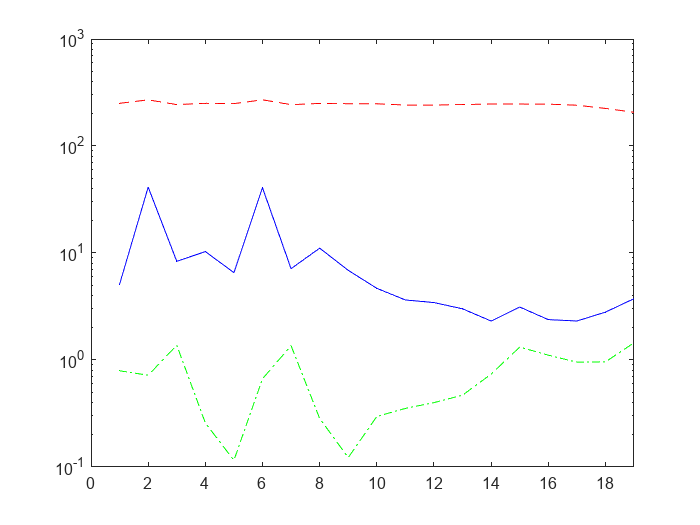

    9      19    2.442354e+01    0.000e+00

% Train NN
iterations = 5000;


[parametersV,parameterNames,parameterSizes] = parameterStructToVector(parameters);
parametersV = extractdata(parametersV);

orient  = [0 90];
g  = calc_g(orient);     % direction(s)
I0 = calc_l2i(g, F0');  % invariants
[I0,PS] = mapminmax(I0);
save PS PS
I0 = dlarray(I0,"BC");
W0 = dlarray(W0',"CB");
S0 = dlarray(stress',"CB");
g  = dlarray(g,"CB");
F0 = dlarray(F0,"CB");

global monitor iter L1_fig L2_fig L3_fig
monitor = true;
if monitor
    % Initialize the variable
    L1_fig = [];
    L2_fig = [];
    L3_fig = [];
    iter = 0;
end

objFun = @(parameters) objectiveFunction(parameters,I0,W0,S0,g,F0,parameterNames,parameterSizes);
nvars = numel(parametersV);
ub = 2 * ones(1,nvars);
lb = -ub;

options = optimoptions("fmincon", ...
    'Display','iter', ...
    HessianApproximation="lbfgs", ...
    MaxIterations=iterations, ...
    MaxFunctionEvaluations=iterations, ...
    OptimalityTolerance=1e-5,...
    SpecifyObjectiveGradient=true);
parametersV = fmincon(objFun,parametersV,[],[],[],[],lb,ub,[],options);

% parametersV = fmincon(objFun,parametersV,[],[],[],[],[],[],[],options);
% parametersV = fminunc(objFun,parametersV,options);

% options = optimoptions("particleswarm", ...
%     'Display','iter', ...
%     MaxIterations=iterations, ...
%     UseParallel=true);
% parametersV = particleswarm(objFun,numel(parametersV),lb,ub);

% options = optimset('Display','iter', ...
%     MaxIter=iterations, ...
%     TolFun=1e-5);
% parametersV = fminsearch(objFun,parametersV,options);
parameters = parameterVectorToStruct(parametersV,parameterNames,parameterSizes);
save("parameters.mat","parameters");
F0 = extractdata(F0);

% evaluate
% orient  = [0,90];
g  = calc_g(orient);     % direction(s)
I0 = calc_l2i(g, F0')';  % invariants
load PS PS
I0 = mapminmax('apply',I0,PS);
% I0 = dlarray(I0,"BC");
W_pred = model(parameters,I0);

figure
hold on
plot(W_pred(1,:) - W_pred(1,1),W0,'b*');
pline = [min(W0) ceil(max(W0)*1000)/1000];
plot(pline,pline,'r-');
hold off

% S0pred = calc_sig(g, extractdata(W_pred(2:end,:))', F0');
S0pred = calc_sig(g, W_pred(2:end,:)', F0');

figure; hold on
plot(F0(1,:),S0(1,:))
plot(F0(1,:),S0pred(:,1))
hold off
figure; hold on
plot(F0(2,:),S0(2,:))
plot(F0(2,:),S0pred(:,2))
hold off

function [loss,gradientsV] = objectiveFunction(parametersV,I0,W0,S0,g,F0,parameterNames,parameterSizes)

% Convert parameters to structure of dlarray objects.
parametersV = dlarray(parametersV);
parameters = parameterVectorToStruct(parametersV,parameterNames,parameterSizes);

% Evaluate model loss and gradients.
[loss,gradients , L1,L2,L3] = dlfeval(@modelLoss,parameters,I0,W0,S0,g,F0);

global monitor iter L1_fig L2_fig L3_fig fig_L1
if monitor
    iter = [iter;iter(end)+1];
    L1_fig = [L1_fig;extractdata(L1)];
    L2_fig = [L2_fig;extractdata(L2)];
    L3_fig = [L3_fig;extractdata(L3)];

    % % Update the plot in the specified axes
    fig_L1 = semilogy(  iter(2:end),L1_fig,'b-',...
        iter(2:end),L2_fig,'r--',...
        iter(2:end),L3_fig,'g-.');

    % Adjust the plot limits if necessary
    xlim([0, iter(end)]);
    % ylim([-10,10])

    % Update the plot
    drawnow;
end

% Return loss and gradients for fmincon.
gradientsV = parameterStructToVector(gradients);
gradientsV = extractdata(gradientsV);
loss = extractdata(loss);

end

function [loss,gradients, L1,L2,L3] = modelLoss(parameters,I0,W0,S0,g,F0)

% model_pred = forward(net,I0);
model_pred = model4train(parameters,I0);
W0Pred = model_pred(1,:);
mseW = custom_l2loss(W0Pred, W0);

% Calculate derivatives with respect to I0.
model_dWI = model_pred(2:end,:);
gradientsW = dlgradient(sum(W0Pred,"all"),{I0},EnableHigherDerivatives=true);
dW_auto = gradientsW{1}(:,:);
msedWI = custom_l2loss(model_dWI,dW_auto);
% % FDM Derivative
% delI = 1e-6;
% dW_FDM = zeros(size(I0));
% for i=1:size(I0,1)
%     v = zeros(size(I0,1),1);
%     v(i) = 1;
%     delI_i = delI * v;
%     Wp = forward(net,I0 + delI_i);
%     Wn = forward(net,I0 - delI_i);
%     dW_FDM(i,:) = (Wp(1,:)-Wn(1,:)) / (2*delI);
% end
% msedWI = custom_l2loss(model_dWI,dW_FDM);

% Calculate stresses corresponding to the identified W and dWI
S0pred   = dlarray(zeros(size(F0,2),2),"BC");

% Cauchy stress calculation
for i = 1:size(F0,2)
    % Calculate S'
    S_PK2 = (model_dWI(1,i).*eye(3));
    S_PK2_4 = zeros(3);
    for j = 2:size(model_dWI,1)
        g_temp = g(j-1,:);
        S_PK2_4   = S_PK2_4 + model_dWI(j,i) .* (g_temp(:) * g_temp(:).');
    end
    S_PK2 = 2 * (S_PK2 + S_PK2_4);
    % Calculate pressure, using BC: sigma_33 = 0
    % p      = F0(3,i)^2 .* S_PK2(3,3);
    % Calculate sigma_11 & sigma_22
    % S0pred(1,i)  = F0(1,i)^2 .* S_PK2(1,1) - p;
    % S0pred(2,i)  = F0(2,i)^2 .* S_PK2(2,2) - p;
    S0pred(1:2,i)  = F0(1:2,i).^2 .* [S_PK2(1,1) ; S_PK2(2,2)] - (F0(3,i)^2 .* S_PK2(3,3));
end
mseS = custom_frobenius_norm(S0pred,S0);


% Calculate Hessain
dWII = cell(1,size(dW_auto,1));
for i = 1:size(dW_auto,1)
    dWII{i} = dlgradient(sum(model_dWI(i,:),"all"),{I0},EnableHigherDerivatives=true);
end
H = dlarray(zeros(size(dW_auto,1),size(dW_auto,1)),"BC");
H_trans = H;
mseH = dlarray(zeros(1),"BC");
mseM = dlarray(zeros(1),"BC");
for i = 1:size(dW_auto,2)
    % Enforce symmetry on Hessain
    for j = 1:size(dW_auto,1)
        dWII_temp = dWII{j}{1}(:,i);
        H(j,:) = dWII_temp(:).';
        H_trans(:,j) = dWII_temp(:);
    end
    mseH = mseH + custom_frobenius_norm(H,H_trans);

    minor = dlarray(zeros(size(H,1),1),"BC");
    minor(1) = max(-custom_det(H(1)),0);
    for j = 2:size(H,1)-1
        H_temp = H;
        H_temp(j+1:end,:) = [];
        H_temp(:,j+1:end) = [];
        minor(j) = max(-custom_det(H_temp),0);
    end
    minor(j+1) = max(-custom_det(H),0);
    mseM = mseM + max(minor(:));
end


% Calculated loss to be minimized by combining errors.
a1 = 1;
a2 = 0.1;
a3 = 0.01;
%
L1 = mseW + msedWI;
L2 = mseS;
L3 = (mseH + mseM) / numel(W0);
% loss = (L1^2 + L2^2 + L3^2) / (L1 + L2 + L3);
% loss = (L1^2 + L2^2) / (L1 + L2);
loss =    a1 * L1 ...
    + a2 * L2 ...
    + a3 * L3;

% Calculate gradients with respect to the learnable parameters.
gradients = dlgradient(loss,parameters);

end

function mse = custom_l2loss(y,t)
mse = sum((y-t).^2,"all") / numel(y) * size(y,1);
end

function mfd = custom_frobenius_norm(y,t)
mfd = (y - t);
mfd = sum(sqrt(sum(mfd.^2,2)),1) / numel(y) * size(y,2);
end

function cdet = custom_det(dl_M)
M_size = size(dl_M,1);
switch M_size
    case 1
        cdet = dl_M;
    case 2
        cdet = dl_M(1).*dl_M(4) - dl_M(2).*dl_M(3);
    case 3
        Ma = [dl_M(5) dl_M(6) ; dl_M(8) dl_M(9)];
        Mb = [dl_M(4) dl_M(6) ; dl_M(7) dl_M(9)];
        Mc = [dl_M(4) dl_M(5) ; dl_M(7) dl_M(8)];
        cdet = dl_M(1).*custom_det(Ma) - dl_M(2).*custom_det(Mb) + dl_M(3).*custom_det(Mc);
end
end